# Pendientes/ideas:

- Añadir slider al propagador que muestre cada frente del plano transversal para ver su evolucion

- Patron no se forma con 5 focos al poner l = 2

delete(gcp('nocreate'));
clearvars;
close all force;
clear;
clc;

# **Experimental high-dimensional quantum key distribution with orbital angular momentum**

Simular circuito de la implementacion :

-     Suponer fuente Gaussiana.

-     Paso por P.

-     Paso por SPP.

-     Paso por M.

-     Sistema posterior a M.

**Set-up del espacio**

% Algunos parametros fisicos
lambda = 633E-9; % nm
w0 = 3e-3;
k = 2*pi/lambda;

% Ventana numerica
%leng =0.5 * 1e-3; % mm
% auxiliar
leng = 20*w0;
L = 2*leng;
Nyquist = 2*L/lambda

Nyquist = 3.7915e+05

%NN = 2^nextpow2(Nyquist)
NN = 2^9

NN = 512


NV = -NN/2:NN/2-1;
dx = L/NN;
xs = NV*dx;
[X, Y] = meshgrid(xs, xs);

kmax = pi/dx;
kxs = kmax*(2/NN)*NV;
[KXs, KYs] = meshgrid(kxs, kxs);

R = sqrt(X.^2 + Y.^2);
KTs = sqrt(KXs.^2 + KYs.^2);
theta = atan2(Y, X);

# **Carga Topológica**

l = 1;
p = 1;

# **Fuente Inicial Gaussiana (Haz en el origen)**

## **Fuente Haz Gaussiano**

tic;
E0 = exp(-R.^2 / w0^2);
toc;

Elapsed time is 0.001794 seconds.


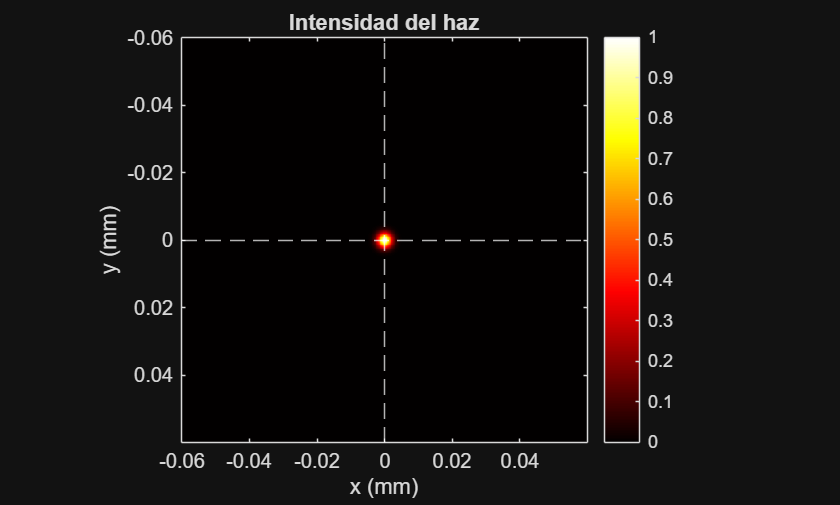

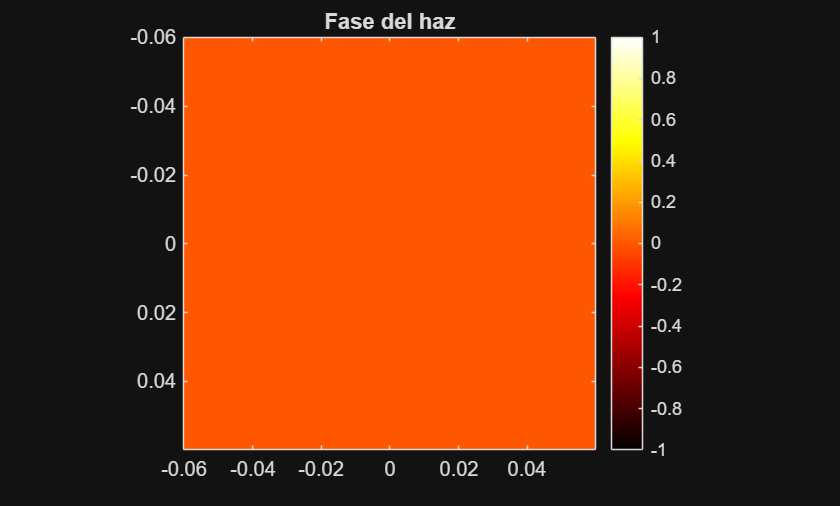

visualizacion(xs, E0);

# **Haz propagado antes de pasar por SPP**

## **Propagación inmediatamente anterior a pasar por SPP**

**Cálculo de la distancia de Rayleigh**

zR = pi * w0^2 / lambda

zR = 44.6672

z = zR/5

z = 8.9334

**Campo despues de propagarse**

Elapsed time is 0.119325 seconds.


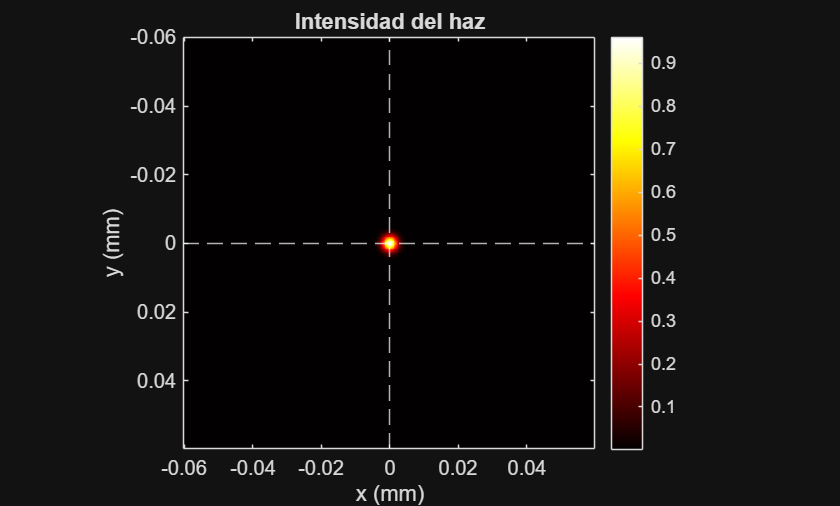

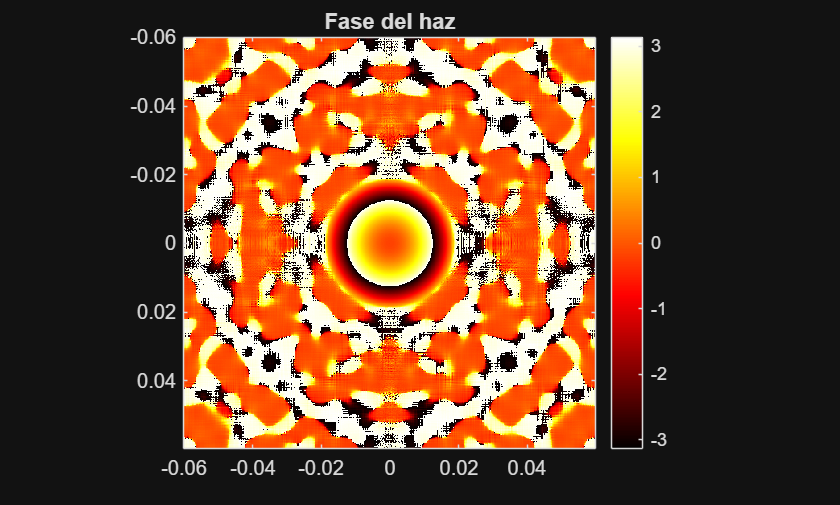

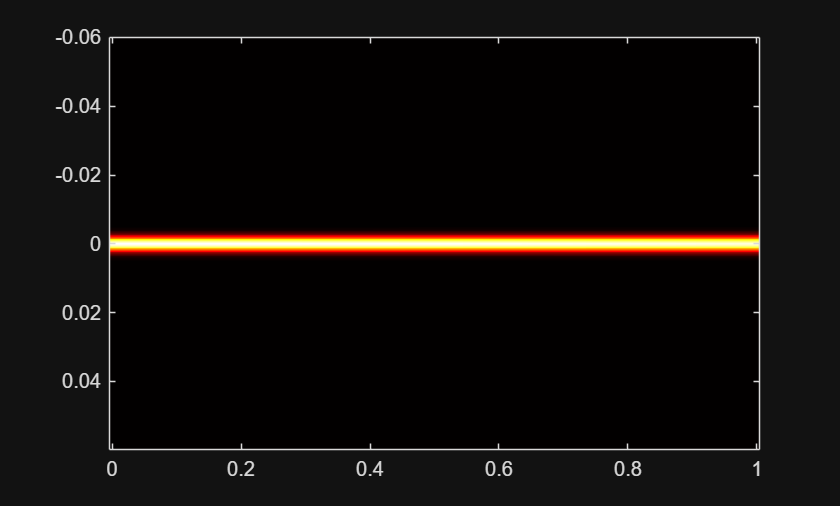

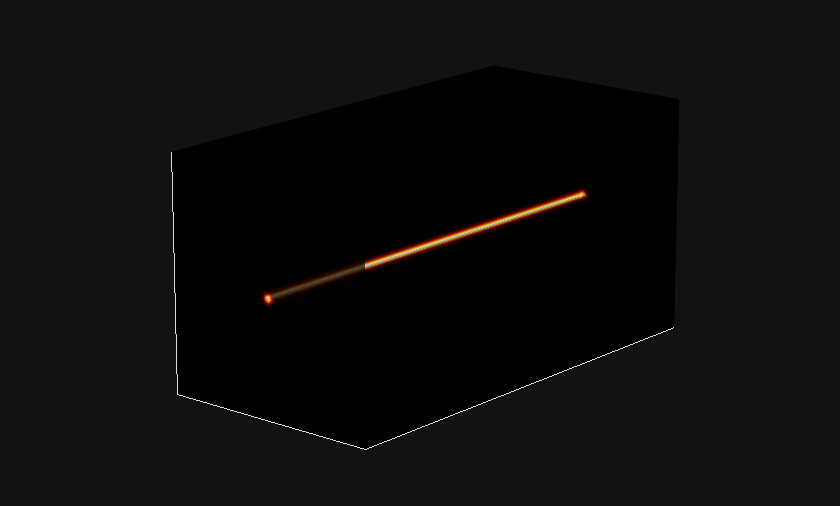

[Ez, E1, Eprop] = Propagador(E0, NN, xs, z, KTs, k);

Eproptotal = Eprop;
size(Eproptotal)

ans =    512   101


# **Haz en SPP**

**Propiedades de LG**

tic;
E1_gpu = gpuArray(E1);
R_gpu = gpuArray(R);
theta_gpu = gpuArray(theta);

%C_LG = sqrt( (2 * factorial(p)) / (pi * factorial(abs(l) + p) * w0^2) );

%termino1 = (R_gpu * sqrt(2) / w0).^abs(l);
termino2 = exp(1i * l * theta_gpu);

%eval_Laguerre = 2 * R_gpu.^2 / w0^2;
%Laguerre = laguerre_propio(p, abs(l), eval_Laguerre);

%E_LG_gpu = C_LG .* termino1 .* Laguerre .* E1_gpu .* termino2;
E_LG_gpu = E1_gpu .* termino2;

E_LG = gather(E_LG_gpu);
toc;

Elapsed time is 0.014527 seconds.


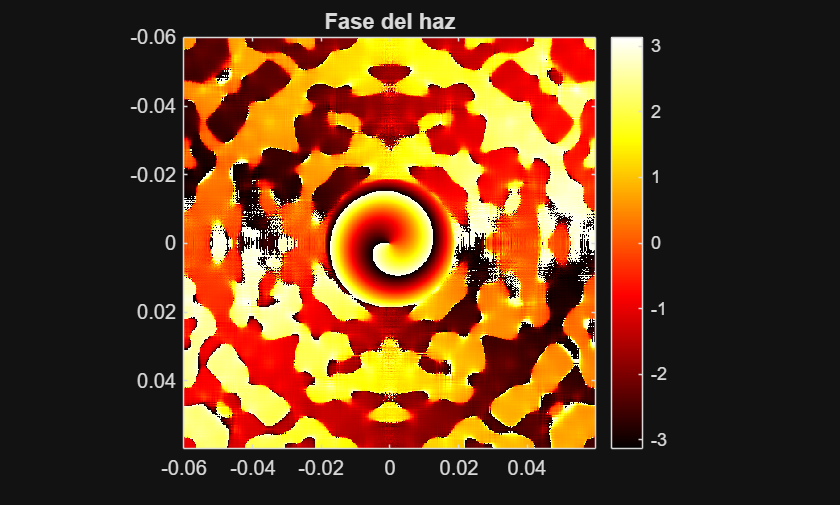

visualizacion(xs, E_LG);

# **Haz propagado antes de pasar por M**

## **Propagación inmediatamente anterior a pasar por M**

Elapsed time is 0.071761 seconds.


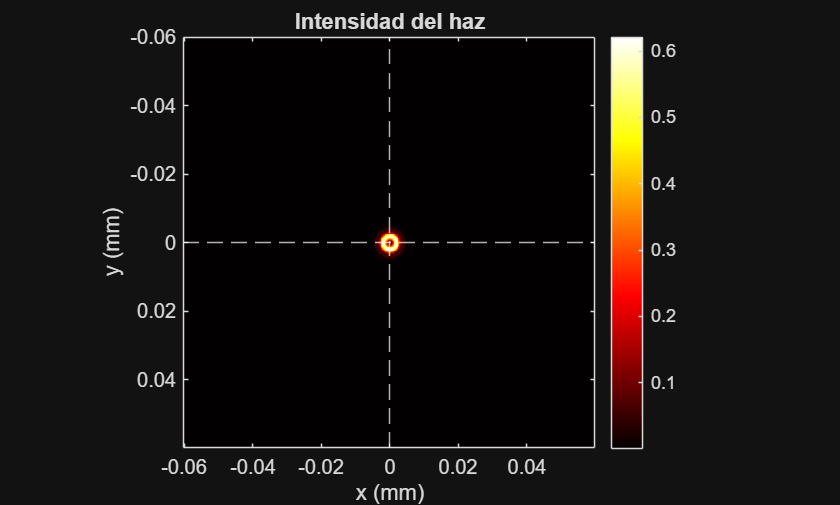

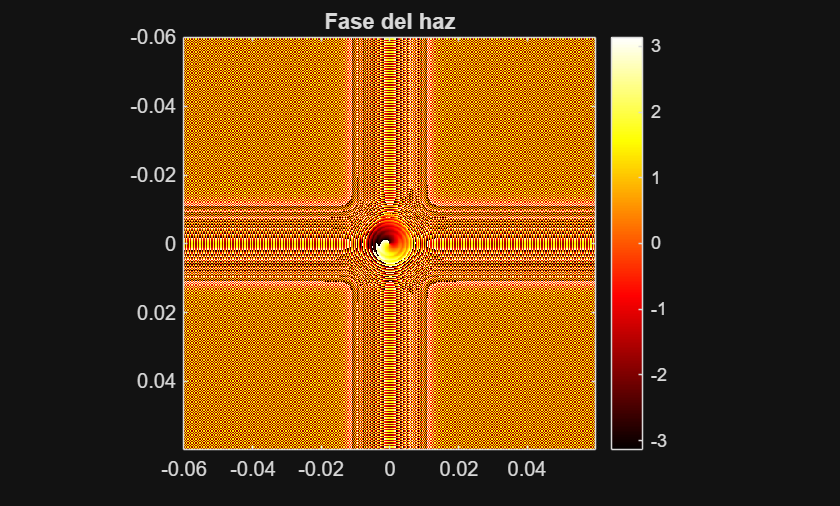

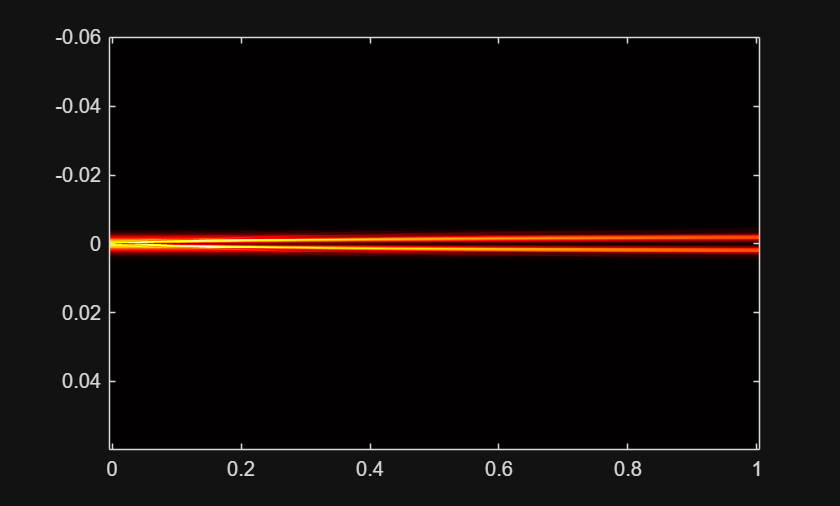

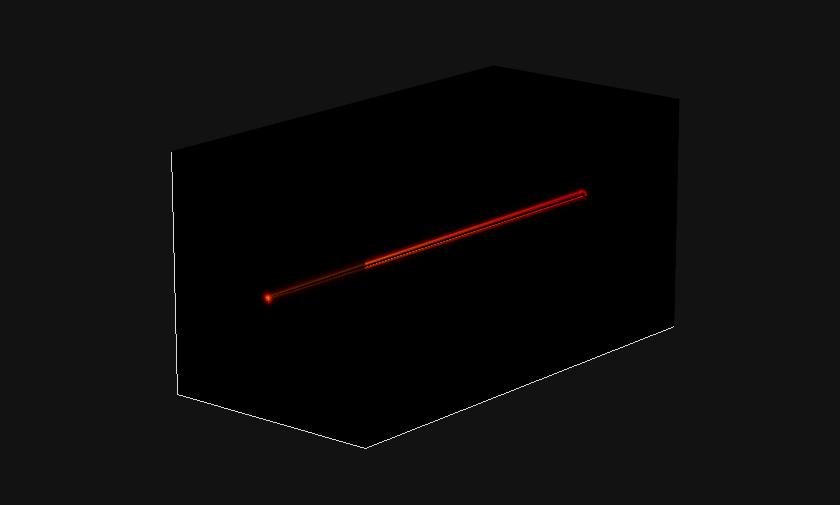

[Ez, E2, Eprop] = Propagador(E_LG, NN, xs, z, KTs, k);

Eproptotal = cat(2, Eproptotal, Eprop);
size(Eproptotal)

ans =    512   202


# **Generación de M (Blazed grating)**

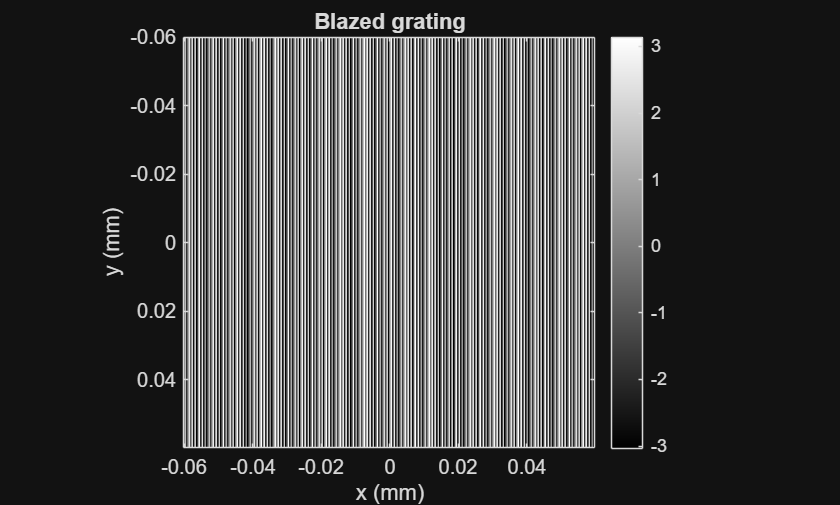

% grating constant
%d = 0.1e-3;
d = 1e-3;
%leng = 10*w0;

gamma = 2*pi/d;

%M1 = exp(1i * rem(gamma * (X + leng), 2*pi))
M1 = exp(1i * gamma * (X + leng));

figure;
imagesc(xs, xs, rem(angle(M1), 2*pi));
colormap gray
colorbar
axis image;
xlabel('x (mm)')
ylabel('y (mm)')
title('Blazed grating')

# **Generación de M (Sinusoidal grating)**

m = 0.8;
fo = 500;
w = 3e-3;
%{ 
%rectX = 0.5 * (abs(X) == w) + 1 * (abs(X) < w)
%rectY = 1/2 * (abs(Y) == w) + 1 * (abs(Y) < w)
tA = (1/2 + m/2 * cos(2*pi*fo*X)) %.*rectX.*rectY
figure
plot(xs, 1/2 + m/2 * cos(2*pi*fo*xs))

figure;
imagesc(xs, xs, tA);
colormap gray
colorbar
axis image;
xlabel('x (mm)')
ylabel('y (mm)')
title('Sinusoidal grating')

# **Generación de M (Binary grating)**

% Una pequeña trampita
Bi = 0 >= cos(2*pi*fo*X) %.*rectX.*rectY
figure
plot(xs, 0 >= cos(2*pi*fo*xs))
yline(2, "r--")

figure;
imagesc(xs, xs, Bi);
colormap gray
colorbar
axis image;
xlabel('x (mm)')
ylabel('y (mm)')
title('Binary grating')
%}

# **Aplicar segundo SPP**

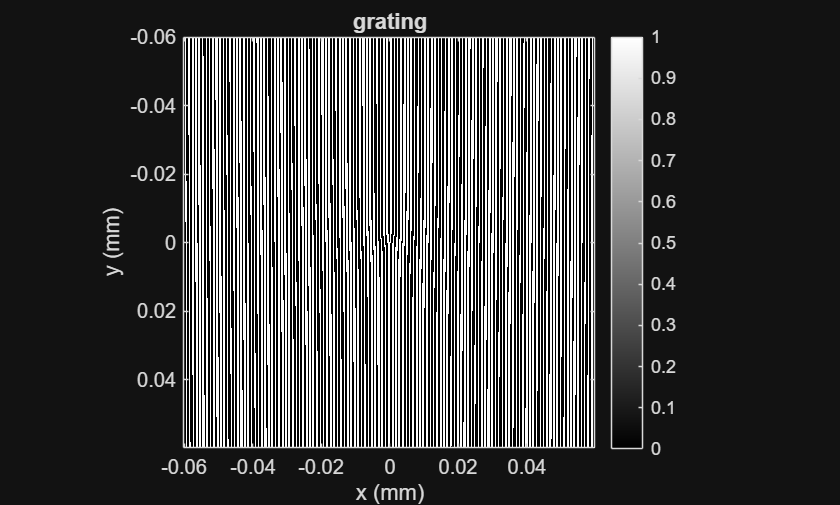

M_SPP = exp(1i * 1 * theta);

M = M_SPP .* M1;
%M = M_SPP .* tA
%M = M_SPP .* Bi

M = 0.5 + 0.5*sign(cos(angle(M))) ;

figure;
imagesc(xs, xs, M);
colormap gray

Elapsed time is 0.005302 seconds.


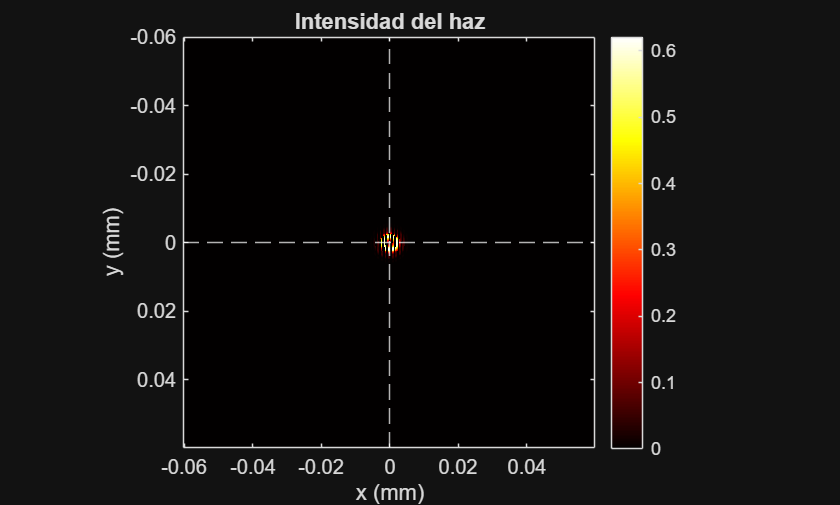

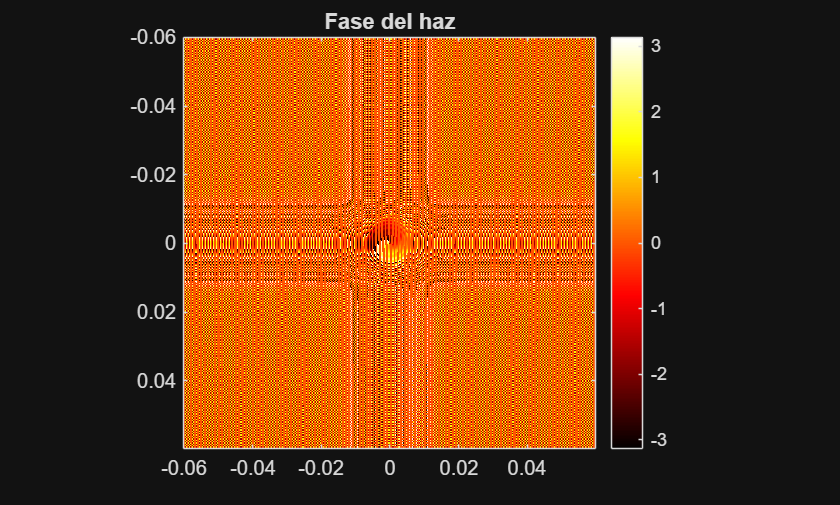

colorbar

Elapsed time is 0.022847 seconds.


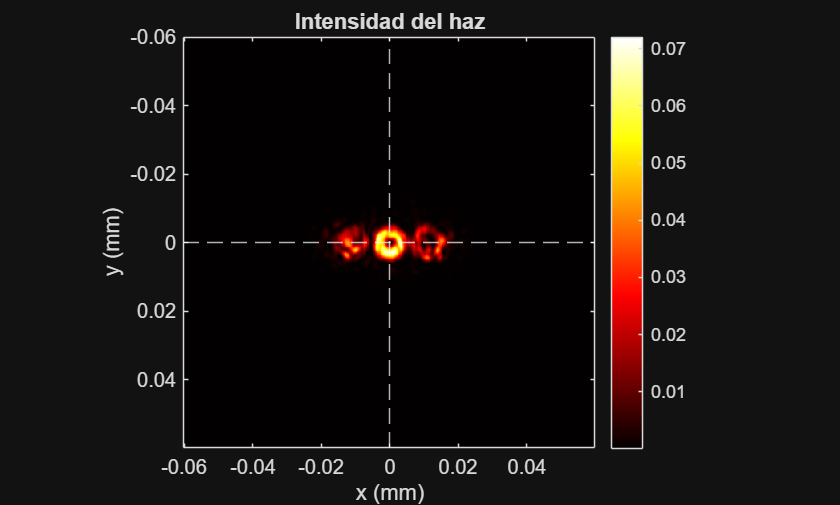

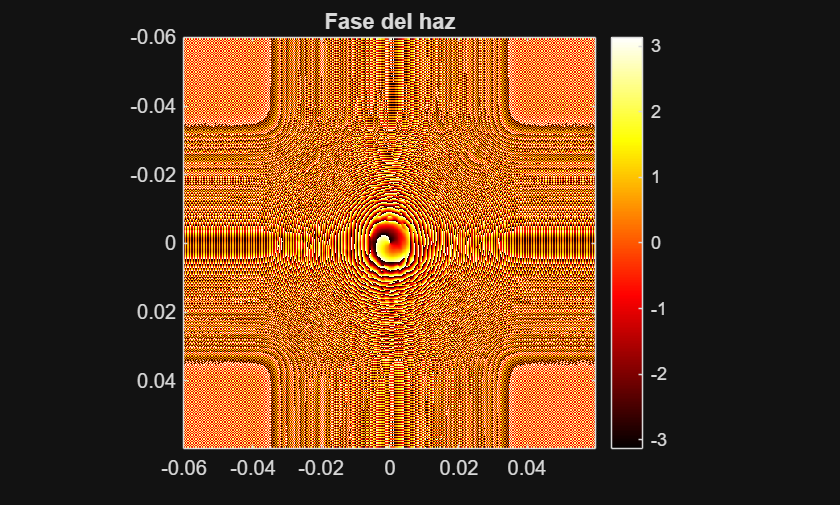

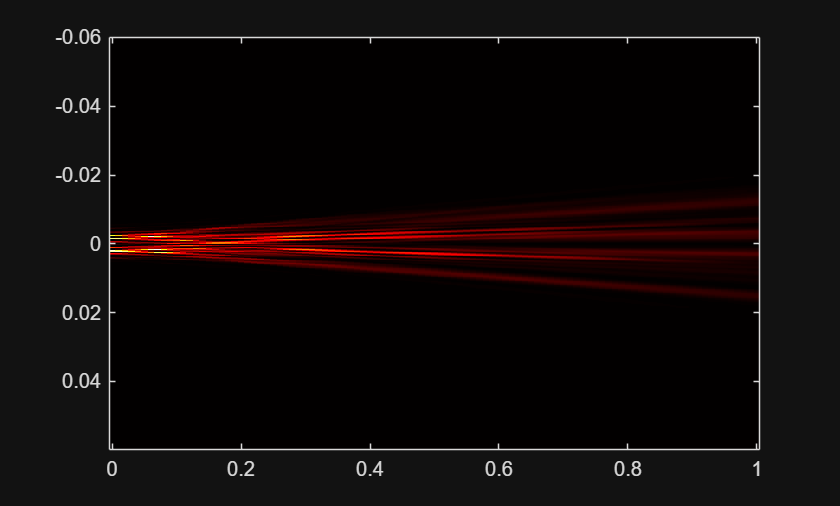

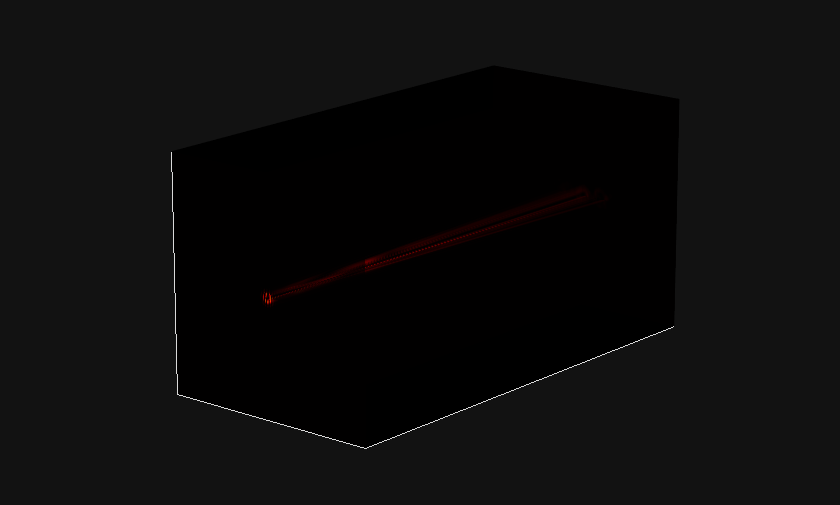

axis image;
xlabel('x (mm)')
ylabel('y (mm)')

title('grating')

# **Paso por M (**fork-shaped**)**

tic;

ans =    512   303


E2_gpu = gpuArray(E2);
M_gpu = gpuArray(M);

EM_gpu = E2_gpu .* M_gpu;

EM = gather(EM_gpu);
toc;
visualizacion(xs, EM);

# **Haz propagado después de pasar por M**

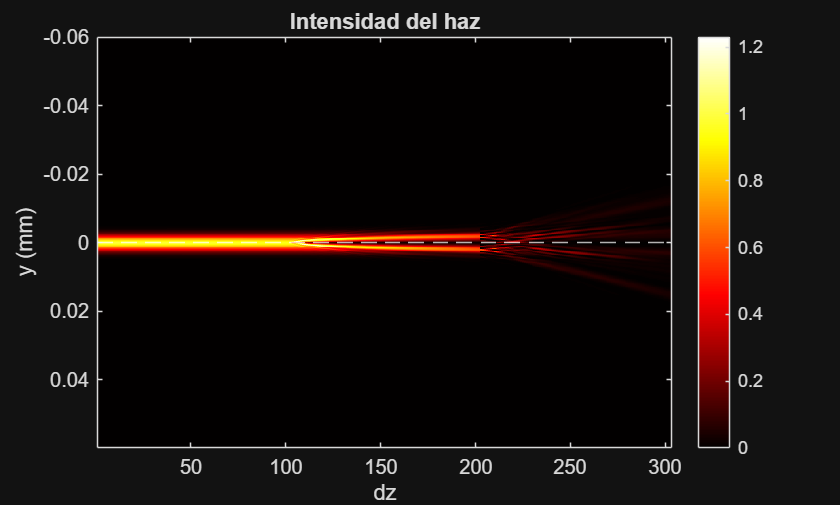

z = 2*zR/5;
[Ez, EM1, Eprop] = Propagador(EM, NN, xs, z, KTs, k);
Eproptotal = cat(2, Eproptotal, Eprop);

size(Eproptotal)

# **Paso por lente delgada (thin lens)**

# **Propagacion completa**

figure;
imagesc(size(Eproptotal(1)),xs, abs(Eproptotal).^2);
colormap hot % se ve más chido
colorbar
xlabel('dz')
ylabel('y (mm)')
title('Intensidad del haz')
yline(0, "w--")

## **Funciones**

function [] = visualizacion(x, E)
    figure;
    imagesc(x, x, abs(E).^2);
    colormap hot % se ve más chido
    colorbar
    axis image;
    xlabel('x (mm)')
    ylabel('y (mm)')
    title('Intensidad del haz')
    xline(0, "w--")
    yline(0, "w--")
    
    figure;
    imagesc(x, x, angle(E));
    colormap hot
    colorbar
    axis image;
    title('Fase del haz');
end

function [Ez, E1, Eprop] = Propagador(E0, NN, xs, z, KTs, k)
    nz = 100;
    dz = z/nz;
    Ez = zeros(NN,NN,nz+1);
    
    % Tipo de propagacion: Paraxial
    Prop = exp(1i*(-0.5*(KTs.^2)/k)*dz);
    
    % Pasar a GPU
    E0_gpu = gpuArray(E0);
    Prop_gpu = gpuArray(Prop);
    Ez_gpu = gpuArray(Ez);
    
    Ez_gpu(:,:,1) = E0_gpu;
    
    tic;
    F = fftshift(fft2(fftshift(E0_gpu)));
    for ii=1:nz
        F = F .* Prop_gpu;
        A = ifftshift(ifft2(ifftshift(F)));
        Ez_gpu(:,:,ii+1) = A;
    end
    toc;
    
    % Obtener de la GPU
    Ez = gather(Ez_gpu);
    E1 = gather(Ez_gpu(:,:,end));

    % Tensor 3D
    squeeze(Ez(end/2,:,:));
    
    % Visualizacion
    zs = (0:dz:z)/z;

    visualizacion(xs, E1)
    
    %figure;
    %imagesc(xs,xs,abs(Ez(:,:,end)).^2), axis equal, colormap hot;
    Eprop = squeeze(Ez(end/2,:, :));
    
    figure;
    imagesc(zs,xs, abs(Eprop(:,:)).^2), colormap hot;

    figure;
    [XX, YY, ZZ] = meshgrid(xs,xs,zs);
    xslice = 0.0;
    yslice = 0.0;
    zslice = [zs(1), zs(end)];
    
    hy = slice(XX, YY, ZZ, abs(Ez).^2, xslice, yslice, zslice);
    rotate(hy,[-1,0,0],90)
    set(gca,'Color','k')
    set(hy,'EdgeColor','none',...
        'FaceAlpha','0.65');
    camproj('perspective')
    colormap(hot);
    axis square, 
    shading interp, lighting phong
    set(gca,'XTick',[], 'YTick', [], 'ZTick',[])
    pbaspect([1 2 1])
    view(40,16)
end

function L = laguerre_propio(p, a, x)
    L = zeros(size(x));
    for k = 0:p
        coef = (-1)^k / factorial(k) * nchoosek(p + a, p - k);
        L = L + coef * x.^k;
    end
end